# Project 6 (Aircraft Descent Profile)

%{
Aircraft descent profile
   originally from ES115 Engineering Computer Applications, Module 2
   project bank, project 12
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   -
%}

clc
clear

% define initial cruising speed and target landing altitude
ICv = 240; % the initial cruising speed in m/s
IAlt = 10000 % the initial altitude in m

IAlt = 10000

targetH = 0; % the target landing altitude in m

% simulate vertical descent while enforcing maximum and minimum speed
%constraints
vMax = 260

vMax = 260

vMin = 70

vMin = 70

t = 0:1:2000;
dt = 1;
alt = zeros(size(t));
spd = zeros(size(t));
vs = zeros(size(t));
alt(1) = 10000;
spd(1) = 240;
for i = 2:length(t)
    if alt(i-1) <= targetH
        alt(i:end) = targetH;
        spd(i:end) = spd(i-1);
        break
    end
     if alt(i-1) > 3000
        vs(i) = -15;
    elseif alt(i-1) > 1000
        vs(i) = -5;
    else
        vs(i) = -2;
     end
      alt(i) = alt(i-1) + vs(i)*dt;
      spd(i) = spd(i-1) - 0.05;
        spd(i) = max(min(spd(i), vMax), vMin);
    
end
valid = alt > targetH | [true diff(alt)~=0];
t = t(valid);
alt = alt(valid);
spd = spd(valid);

% identify the phases of descent
steadyD = alt > 3000;
levelingD = alt <= 3000 & alt > 1000;
finalA = alt <= 1000;

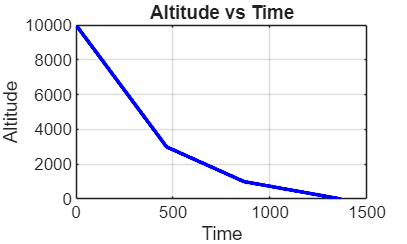

% plot altitude vs time
plot(t, alt, 'b-', 'LineWidth', 2)
title('Altitude vs Time')
xlabel('Time')
ylabel('Altitude')
grid on

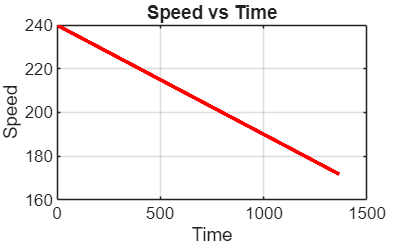

% plot speed vs time
plot(t, spd, 'r-', 'LineWidth', 2)
title('Speed vs Time')
xlabel('Time')
ylabel('Speed')
grid on

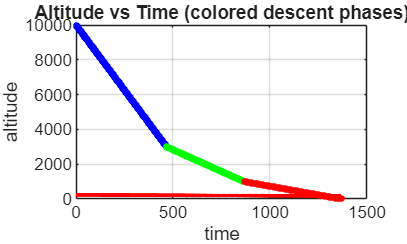

% colored phase plot for altitude to show the phases of descent
hold on
plot(t(steadyD), alt(steadyD), 'b.', 'MarkerSize', 10, 'DisplayName', 'Steady Descent')
plot(t(levelingD), alt(levelingD), 'g.', 'MarkerSize', 10, 'DisplayName', 'Leveling')
plot(t(finalA), alt(finalA), 'r.', 'MarkerSize', 10, 'DisplayName', 'Final Approach')
hold off
title('Altitude vs Time (colored descent phases)')
xlabel('time')
ylabel('altitude')